# Using LBP Features to Differentiate Images by Texture

Read images that contain different textures.

brickWall = imread('bricks.jpg');
rotatedBrickWall = imread('bricksRotated.jpg');
carpet = imread('carpet.jpg');

Display the images.

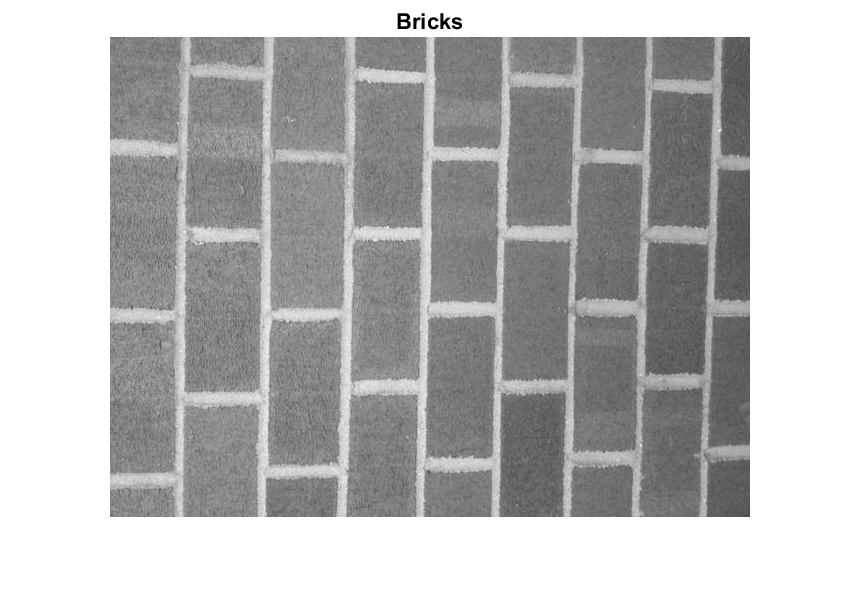

figure
imshow(brickWall)
title('Bricks')

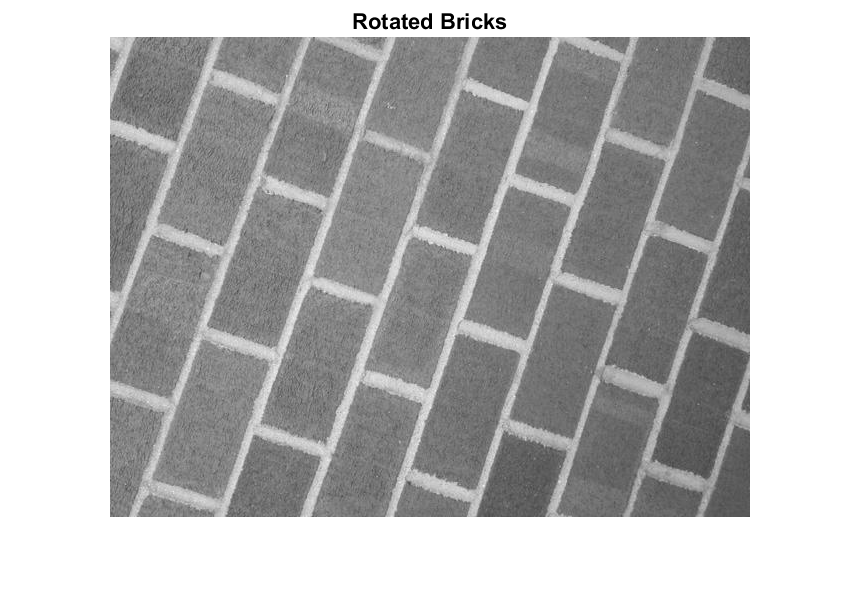


figure
imshow(rotatedBrickWall)
title('Rotated Bricks')

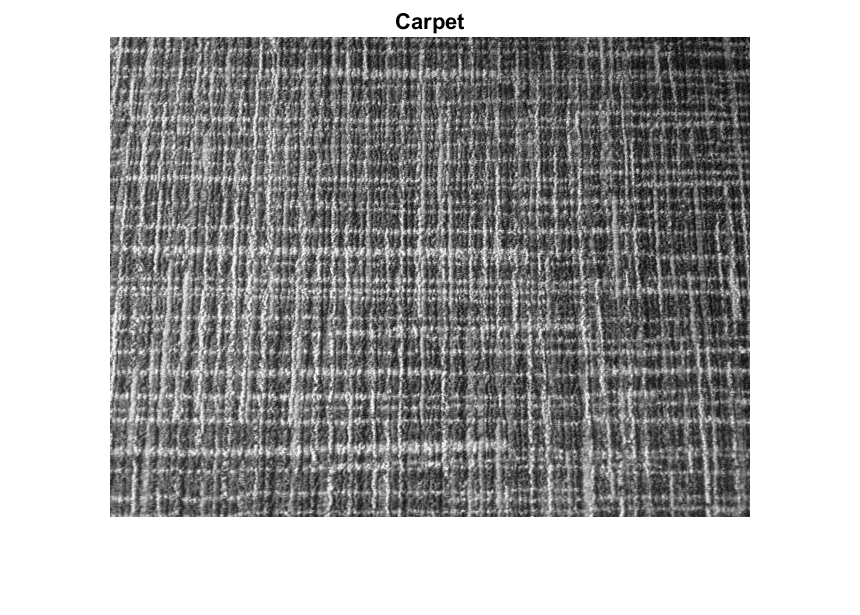


figure
imshow(carpet)
title('Carpet')

Extract LBP features from the images to encode their texture information.

lbpBricks1 = extractLBPFeatures(brickWall,'Upright',false);
lbpBricks2 = extractLBPFeatures(rotatedBrickWall,'Upright',false);
lbpCarpet = extractLBPFeatures(carpet,'Upright',false);

Gauge the similarity between the LBP features by computing the squared error between them.

brickVsBrick = (lbpBricks1 - lbpBricks2).^2;
brickVsCarpet = (lbpBricks1 - lbpCarpet).^2;

Visualize the squared error to compare bricks versus bricks and bricks versus carpet. The squared error is smaller when images have similar texture.

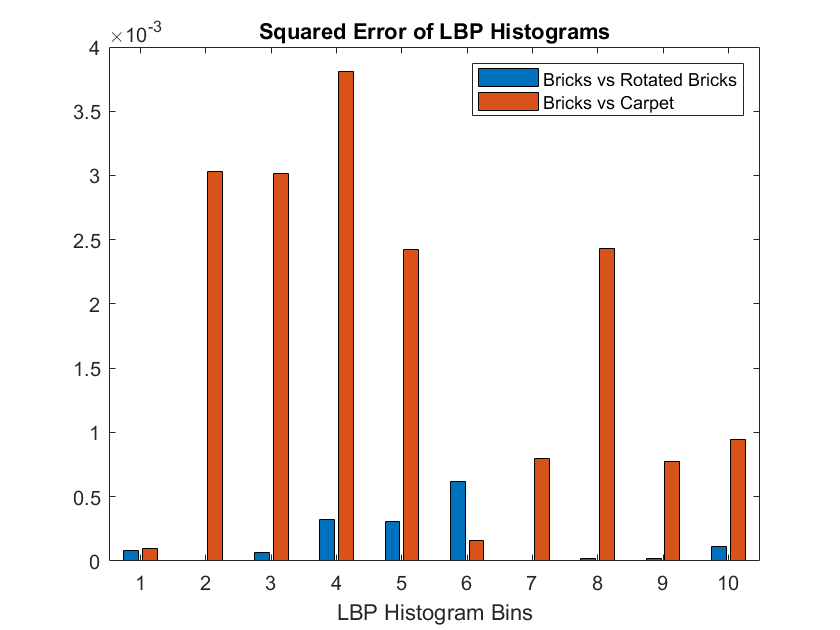

figure
bar([brickVsBrick; brickVsCarpet]','grouped')
title('Squared Error of LBP Histograms')
xlabel('LBP Histogram Bins')
legend('Bricks vs Rotated Bricks','Bricks vs Carpet')

*Copyright 2015 The MathWorks, Inc.*